%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 4.1
% <Demetrios Kechris dkechris@bu.edu>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all; clc;
rng('default')  % For reproducibility of data and results

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.1(a)
% create data set, mean, cov, average cov
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%data is row1 = x, row2 = y
Dneg = [-1 0.5; -1 0.5; -1 0.5; -1 0.5; -1 0.5; -1 0.5; -1 0.5; -1 0.5; -1 0.5; -11 0.5; -1 -1.5; -1 -1.5; -1 -1.5; -1 -1.5; -1 -1.5; -1 -1.5; -1 -1.5; -1 -1.5; -1 -1.5; -11 -1.5]

Dneg =    -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
   -1.0000    0.5000
  -11.0000    0.5000


Dpos = [1 1.5; 1 1.5; 1 1.5; 1 1.5; 1 1.5; 1 1.5; 1 1.5; 1 1.5; 1 1.5; 11 1.5; 1 -0.5; 1 -0.5; 1 -0.5; 1 -0.5; 1 -0.5; 1 -0.5; 1 -0.5; 1 -0.5; 1 -0.5; 11 -0.5]

Dpos =     1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
    1.0000    1.5000
   11.0000    1.5000


Dneg = transpose(Dneg)

Dneg =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000  -11.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000  -11.0000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000


Dpos = transpose(Dpos)

Dpos =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   11.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   11.0000
    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000


Dtot = [Dneg Dpos]

Dtot =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000  -11.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000  -11.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   11.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   11.0000
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000   -1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000    1.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000


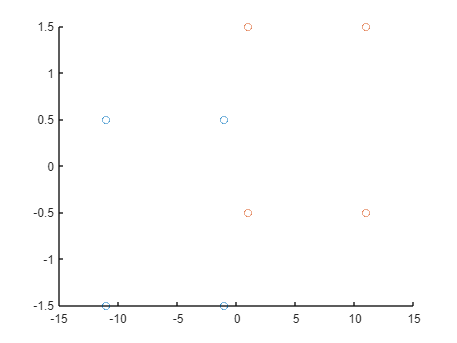


% visualize data
scatter(Dneg(1,:),Dneg(2,:))
hold on
scatter(Dpos(1,:),Dpos(2,:))
hold off


%calc means
meanDneg = XYmean(Dneg)

meanDneg =    -2.0000
   -0.5000


meanDpos = XYmean(Dpos)

meanDpos =     2.0000
    0.5000



%calc cross cov
Dneg_ccov = XYcov(Dneg)

Dneg_ccov =      9     0
     0     1


Dpos_ccov = XYcov(Dpos)

Dpos_ccov =      9     0
     0     1



% Dave cov
Dtot_ccov = (size(Dneg,2)/size(Dtot,2)*Dneg_ccov) + (size(Dpos,2)/size(Dtot,2)*Dpos_ccov)

Dtot_ccov =      9     0
     0     1




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.1(b)
% Compute wLDA, bLDA, and the CCR of the LDA classifier.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Dtot_wlda = calc_wlda(Dneg, Dpos)

ans =     0.1111         0
         0    1.0000


wlda =    -0.4444
   -1.0000


Dtot_wlda =     0.4444
    1.0000


Dtot_blda = calc_blda(Dneg, Dpos, Dtot_wlda)

a =     0.2222    0.5000


b = 0.6944

c =    -0.2222   -0.5000


d = 0.6944

Dtot_blda = 0

Dtot_wblda = [Dtot_wlda; Dtot_blda]

Dtot_wblda =     0.4444
    1.0000
         0


CCR_wblda = CCR(Dneg, Dpos, Dtot_wlda, Dtot_blda)

CCR_wblda = 0.5500


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.1(c)
% Compute wLDA, bLDA, and the CCR of the LDA classifier.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Dtot_wlda_bin = calc_wlda(Dneg, Dpos)

ans =     0.1111         0
         0    1.0000


wlda =    -0.4444
   -1.0000


Dtot_wlda_bin =     0.4444
    1.0000


Dtot_blda_bin = calc_binary_blda(Dneg, Dpos, Dtot_wlda_bin)

z =     0.0556    0.0556    0.0556    0.0556    0.0556    0.0556    0.0556    0.0556    0.0556   -4.3889   -1.9444   -1.9444   -1.9444   -1.9444   -1.9444   -1.9444   -1.9444   -1.9444   -1.9444   -6.3889    1.9444    1.9444    1.9444    1.9444    1.9444    1.9444    1.9444    1.9444    1.9444    6.3889   -0.0556   -0.0556   -0.0556   -0.0556   -0.0556   -0.0556   -0.0556   -0.0556   -0.0556    4.3889


ans =     0.0556   -4.3889   -1.9444   -6.3889    1.9444    6.3889   -0.0556    4.3889


sorted_z =    -6.3889   -4.3889   -1.9444   -0.0556    0.0556    1.9444    4.3889    6.3889


bw =    -7.3889   -5.3889   -3.1667   -1.0000         0    1.0000    3.1667    5.3889    7.3889


bw =    -7.3889   -5.3889   -3.1667   -1.0000         0    1.0000    3.1667    5.3889    7.3889


wbpCCR =     0.5000    0.5250    0.5500    0.7750    0.5500    0.7750    0.5500    0.5250    0.5000


wbnCCR =     0.5000    0.5250    0.5500    0.7750    0.5500    0.7750    0.5500    0.5250    0.5000


Dtot_blda_bin = -1

Dtot_wblda = [Dtot_wlda_bin; Dtot_blda_bin]

Dtot_wblda =     0.4444
    1.0000
   -1.0000


CCR_wblda = CCR(Dneg, Dpos, Dtot_wlda_bin, Dtot_blda_bin)

CCR_wblda = 0.7750

function mean = XYmean(data)
% takes in an array of data (x1; x2; x3; ...)
% returns the mean of each column
    mean = zeros(size(data,1),1);
    for i = 1:size(data,1)
        Imean = sum(data(i,:))/size(data,2);
        mean(i,1) = Imean;
    end
end

function data_cov = XYcov(data)
% takes in an array of data (x1; x2; x3; ...)
% returns covariance of the data, dx;d matrix
    mean = XYmean(data);
    data_norm = (data(:, :) - mean);
    data_cov = 0;
    for i = 1:size(data_norm,2)
        data_cov = data_cov + data_norm(:,i)*transpose(data_norm(:,i));
    end
    data_cov = data_cov / size(data_norm,2);
end

function ave_cov = ave_cov(data1,data2)
    d1_cov = XYcov(data1);
    d2_cov = XYcov(data2);
    Dtot = [data1 data2];
    ave_cov = (size(data1,2)/size(Dtot,2)*d1_cov) + (size(data2,2)/size(Dtot,2)*d2_cov);
end

function wlda = calc_wlda(data1, data2)
% takes in 2 groups of data
% outputs the best Wlda value associated with them
% Wlda is calculated by using a meshgrid from -10 to 10 in increments of .1
    mean1 = XYmean(data1);
    mean2 = XYmean(data2);
    Dtot = [data1 data2];
    Dave_cov = ave_cov(data1, data2);
    %to visualize data
    % data_norm1 = (data1(:, :) - mean1)
    % data_norm2 = (data2(:, :) - mean2)
    % scatter(data_norm1(:,1),data_norm1(:,2))
    % hold on
    % scatter(data_norm2(:,1),data_norm2(:,2))
    % hold off
    
    %{
    % use 10x10x.1 meshgrid to find Wlda
    x = -10:.1:10;
    y = -10:.1:10;
    %[X Y] = meshgrid(x,y)
    % size(x,2)
    % size(y,2)
    output = zeros(size(x,2),size(y,2));
    for i = 1:size(x,2)
        for j = 1:size(y,2)
            % output(i,j) = (transpose(w)*(mean2-mean1))^2/(transpose(w)*Dave_cov*w)
            w = [x(1,i); y(1,j)];
            
            % transpose(w);
            % mean2-mean1;
            top = (transpose(w)*(mean2-mean1))^2;
            bot = transpose(w)*Dave_cov*w;
            output(i,j) = top/bot;
        end
    end
    %output
    
    [M,I] = max(output);
    [M2,I2] = max(M);
    yi = I2;
    xi = I(yi);
    %output(xi, yi)
    wlda = [x(xi); y(yi)];
    %}

    inv(Dave_cov)
    wlda = inv(Dave_cov) * (mean1-mean2)
    if wlda < 0
        wlda = -1*wlda;
    end
end

function blda = calc_blda(data1, data2, wlda)
% b = (ln p2 - ln p1) - 1/2( (mu2)T*S^-1*mu2 -(mu1)T*S^-1*mu1)
    mean1 = XYmean(data1);
    mean2 = XYmean(data2);
    Dtot = [data1 data2];
    Dave_cov = ave_cov(data1, data2);
    Inv_Dave_cov = inv(Dave_cov);

    a = transpose(mean2)*Inv_Dave_cov
    b = transpose(mean2)*Inv_Dave_cov*mean2
    c = transpose(mean1)*Inv_Dave_cov
    d = transpose(mean1)*Inv_Dave_cov*mean1
    
    blda = 0;
    p1 = size(data1,2)/size(Dtot,2);
    p2 = size(data2,2)/size(Dtot,2);
    blda = (log(p2) - log(p1)) - .5*(transpose(mean2)*Inv_Dave_cov*mean2 - transpose(mean1)*Inv_Dave_cov*mean1);
end

function blda = calc_binary_blda(data1, data2, wlda)
    blda = 0;
    Dtot = [data1 data2];
    z = transpose(wlda)*Dtot
    unique(z, 'stable')
    sorted_z = unique(z,'sorted')
    bw = createbw(sorted_z)
    wbpCCR = zeros(1,size(bw,2));
    for i = 1:size(bw,2)
        wbpCCR(i) = CCR(data1, data2, wlda, bw(i));
    end
    wbnCCR = zeros(1,size(bw,2));
    for i = 1:size(bw,2)
        wbnCCR(i) = CCR(data1, data2, -wlda, bw(i));
    end
    wbpCCR
    wbnCCR
    [Mp, Ip] = max(wbpCCR);
    [Mn, In] = max(wbnCCR);
    if Mp(1) > Mn(1)
        blda = bw(Ip(1));
    else
        blda = bw(In(1));
    end
end

function bw = createbw(z)
% function takes in a sorted array and returns an array of length+2
% output is smallest - 1, midpoints between all points z(i), largest + 1 
    bwinner = zeros(1,size(z,2)-1);
    bwfirst = z(1) - 1;
    bwlast = z(size(z,2)) + 1;
    for i = 1:size(z,2)-1
        bwinner(i) = (z(i) + z(i+1)) / 2;
    end
    bw = [bwfirst bwinner bwlast]
end

function CCR = CCR(data1, data2, w, b)
    Dtot = [data1 data2];

    % check CCR for w
    correct = 0;
    for i = 1:size(Dtot,2)
        if (transpose(w)*Dtot(:,i) + b) > 0
            % guess = data2
            % if i in second half of Dtot, correct label is data2
            if i > size(data1,2)
                correct = correct + 1;
            end
        else
            % guess = data1
            % if i in first half of Dtot, correct label is data2
            if i <= size(data1,2)
                correct = correct + 1;
            end
        end
    end
    CCRwp = correct / size(Dtot,2);
        
    % check CCR for negative w
    correct = 0;
    w = -w;
    for i = 1:size(Dtot,2)
        if (transpose(w)*Dtot(:,i) + b) > 0
            % guess = data2
            % if i in second half of Dtot, correct label is data2
            if i > size(data1,2)
                correct = correct + 1;
            end
        else
            % guess = data1
            % if i in first half of Dtot, correct label is data2
            if i <= size(data1,2)
                correct = correct + 1;
            end
        end
    end
    CCRwn = correct / size(Dtot,2);
    if CCRwp > CCRwn
        CCR = CCRwp;
    else
        CCR = CCRwn;
    end
end